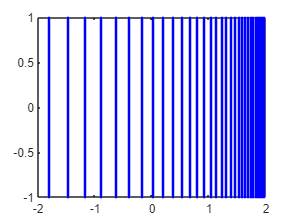

clear all;clc
syms beta W3 D(x)
ga=atan(sin(beta)*tan(pi/120));
D(x)=110-tan(pi/120)*x*1852;
W3(beta,x)=2*sin(2*pi/3)*cos(ga)/(cos(2*ga)+cos(2*pi/3))*D(x);


%先求出当β=90°时的总路线长度
l=cos(pi/3-pi/120)/(cos(-pi/120+pi/3)+cos(pi/120+pi/3));
r=cos(pi/3+pi/120)/(cos(-pi/120+pi/3)+cos(pi/120+pi/3));
eq=x*1852-W3(pi/2,x)*l==-2*1852;
x_list=[vpa(solve(eq,x))];

while x_list(length(x_list))*1852+...
    r*W3(pi/2,x_list(length(x_list)))<2*1852
    eq=1-1852*(x-x_list(length(x_list)))/...
    (W3(pi/2,x_list(length(x_list)))*r+ ...
    W3(pi/2,x_list(length(x_list)))*l)==0.1;
    x_list(length(x_list)+1)=vpa(solve(eq,x));
end
x_list;
for y=-1:0.01:1
    plot(x_list,repmat(y,1,length(x_list)),'b.')
    hold on
end
xlim([-2,2])
ylim([-1,1])
print -dpng 第三问测线图.png%绘出测线

2*length(x_list)

ans = 66

%当β角变化时，稍微倾斜不超过97°，变化幅度不大，η保证测线最短处大于10%
result_x=[zeros(1,length(x_list));x_list];
% tic%测试用
% n=0;%测试用
l=cos(pi/3-pi/120)/(cos(-pi/120+pi/3)+cos(pi/120+pi/3));
r=cos(pi/3+pi/120)/(cos(-pi/120+pi/3)+cos(pi/120+pi/3));
for b=pi/2:pi/360:pi/2+7*pi/180%当β在90°到97°之间取值时，更大的可以不考虑了
    % n=n+1%测试用
    eq=x*1852-W3(b,x)*l==-2*1852;%近似认为西侧覆盖完全
    x_list=[vpa(solve(eq,x))];
    while x_list(length(x_list))*1852+...
        2*tan(b-pi/2)+r*W3(b,x_list(length(x_list))+ ...
        2*tan(b-pi/2))<2*1852
        eq=1-1852*sin(b)*(x-x_list(length(x_list)))/...
        (W3(b,x_list(length(x_list))+2*tan(b-pi/2))* ...
        r+W3(b,x_list(length(x_list))+2*tan(b-pi/2))*l)==0.1;
        x_list(length(x_list)+1)=vpa(solve(eq,x));
    end
    
    if length(x_list)<length(result_x(1,:))
        a=zeros(1,length(result_x(1,:))-length(x_list));
        x_list=[x_list a];%若结果长度小于β=90°时的解，则将在解的后面补充0以标记
    end

    if length(x_list)>length(result_x(1,:))%比南北结果多则直接淘汰该结果
        if x_list(length(x_list))>2%最后一个解若大于2，可以考虑增加一条平行的较短测线解决
            x_list=x_list(1,1:length(x_list)-1);
            if length(x_list)>length(result_x(1,:))
                x_list=repmat(NaN,1,length(result_x(1,:)));%舍掉解全部记为NaN
            end
        else
            x_list=repmat(NaN,1,length(result_x(1,:)));
        end
        b=size(result_x);
        b=b(1);
        result_x(b+1,:)=x_list;
    elseif length(x_list)==length(result_x(1,:))
        b=size(result_x);
        b=b(1);
        result_x(b+1,:)=x_list;
    end
end
result_x%最后答案所有数据从第二行开始的最后一列都不是0，无满足题意解

% toc%测试用
